### Heat Map and Spatial Displacement Map

Plot heatmap

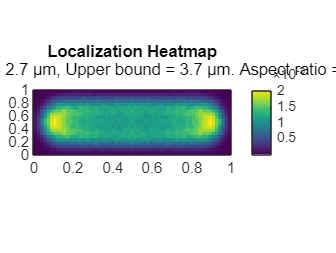

% With Localizaiton Precision as a filter
[raw_heatmap, htMap] = ...
Plot_heatmap_withFilter(Store_track,Store_mask,...
Store_fits,Index,1/num_pix_y,aspt_ratio,locFitCI_UB/pixel_size,...
'on','on',slanCM('viridis'));

figureAddTitle(gcf, 'Localization Heatmap', low_bd, up_bd, aspt_ratio);
SaveFigure(result_folder,'Heat map',gcf,...
    {'fig','png','svg'},slanCM('viridis'))

Plot spatial displacement map

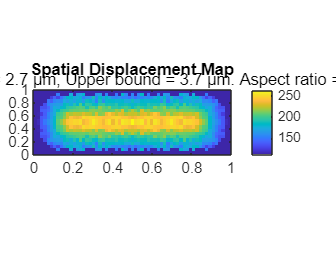

% With Localization Precision as a filter
[raw_spatialDisp, spMap, ~, spMap_cnt] = ...
    Spatial_Displacement_withFilter(Store_track,...
    Store_mask,Store_fits,Index,pixel_size,...
    3,1/num_pix_y,aspt_ratio,0.05,...
    locFitCI_UB/pixel_size,'on','on',slanCM('parula'));

figureAddTitle(gcf, 'Spatial Displacement Map', low_bd, up_bd, aspt_ratio);
SaveFigure(result_folder,'Spatial displacement map',...
    gcf, {'fig','png','svg'},slanCM('parula'))

### Determine cell and nucleoid boundaries

Heat Map with cell and nucleoid boundaries (by exclusion)

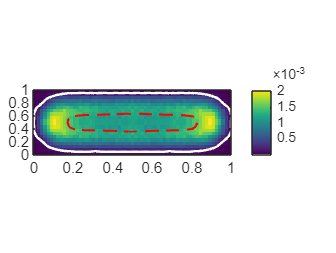

[cell_outline,nuc_outline] = Outline_by_htMap(...
    htMap,raw_heatmap,...
    'kde','gradient',aspt_ratio,...
    num_pix_y,'on','on',10,'off');
SaveFigure(result_folder,'Heat map with boundaries',...
    gcf, {'fig','png','svg'},slanCM('viridis'))

Spatial Displacement Map with cell and nucleoid boundaries (by contour line)

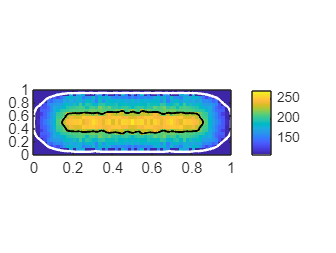

[nuc_contour,cntr_up,cntr_low,~] = Outline_by_spMap(...
    spMap, nuc_outline,'on',cell_outline,...
    aspt_ratio,num_pix_y);
SaveFigure(result_folder,'Spatial displacement map with boundaries',...
    gcf, {'fig','png','svg'},slanCM('parula'))

Heat Map with final nucleoid and cell boundaries

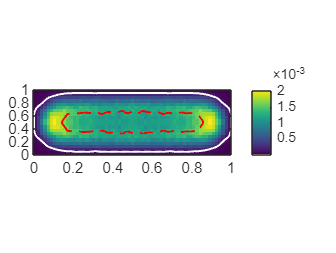

htMap_final_bndy(htMap, cell_outline,...
    nuc_contour{1}, num_pix_y, aspt_ratio,...
    slanCM('viridis'))
SaveFigure(result_folder,'HeatMap with final boundaries',...
    gcf, {'fig','png','svg'},slanCM('viridis'))